%% Clears
close all; 
clc;     
clear;     

% Definir parâmetros para gravação de áudio
Tempo = 5; % Duração do áudio em segundos
FS = 48000;  % Frequência de amostragem de 48 kHz
Nbits = 24; % Resolução de 24 bits
Canais = 1; % Mono

% Gravar áudio
r = audiorecorder(FS, Nbits, Canais); % Preparar para gravar
disp("Gravando audio.");

Gravando audio.


record(r);
pause(Tempo);
stop(r);
disp('Gravação finalizada.');

Gravação finalizada.


Y = getaudiodata(r, 'double'); % Converter para vetor do MATLAB
    
% Salva áudio em um arquivo .wav
audiowrite(['palma.wav'], Y, FS);

% Escutar áudio gravado
sound(Y, FS);
pause(t + 1);

%Abrir arquivos
nome_arquivo_audio = 'violao';
nome_arquivo_impulso = 'palma';
[Y, FS] = audioread([nome_arquivo_audio '.wav']);
[impulso, Fs_impulso] = audioread([nome_arquivo_impulso '.wav']);

% Converte para mono caso seja estéreo
if size(impulso, 2) > 1
    impulso = mean(Y, 2);
end
if size(Y, 2) > 1 
    Y = mean(Y, 2);
end

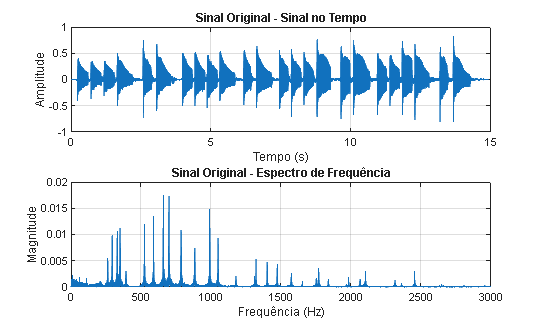

%% Processamento do Áudio
t = (0:length(Y)-1)/FS; % Vetor de tempo

% Plota o sinal original e espectro
graficos(t, Y, FS, 'Sinal Original');

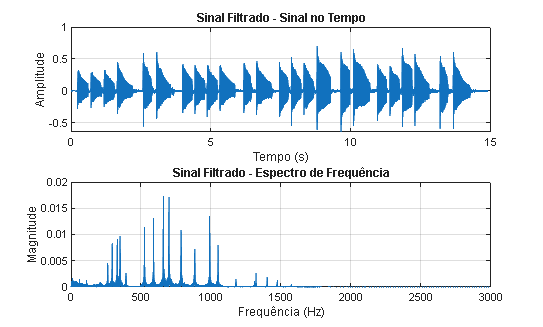

%% Filtro para reconhecimento de notas
% Configuração do filtro passa-banda
freqMin = 60;        % Frequência de corte inferior
freqMax = 1500;      % Frequência de corte superior
ordemFiltro = 100;   % Ordem do filtro FIR

% Projeto do filtro FIR
coefFiltro = fir1(ordemFiltro, [freqMin, freqMax]/(FS/2), 'bandpass');

% Filtragem do sinal
Yfiltrado = filtfilt(coefFiltro, 1, Y);

% Plot do sinal filtrado e seu espectro
graficos(t, Yfiltrado, FS, 'Sinal Filtrado');


%% Identificação de múltiplas notas
% Cálculo do espectro do sinal filtrado
X = fft(Yfiltrado);
N = length(X);

% Magnitude do espectro normalizada
P2 = abs(X / N);
P1 = P2(1:N/2+1);
P1(2:end-1) = 2 * P1(2:end-1); % Correção para espectro unilateral

% Eixo de frequências
frequencias = FS/N * (0:(N/2));

% Configuração para detecção de picos
prominenciaMinima = 0.2 * max(P1);      % Proeminência mínima: 20% do maior pico
distanciaMinimaHz = 5;                  % Distância mínima entre picos em Hz
distanciaMinimaAmostras = round(distanciaMinimaHz * N / FS);

% Detecção dos picos no espectro
[picos, indicesPicos] = findpeaks(P1,'MinPeakProminence', prominenciaMinima,'MinPeakDistance', distanciaMinimaAmostras);

% Ordenação dos picos por magnitude decrescente
[picosOrdenados, idxOrdenados] = sort(picos, 'descend');
frequenciasDominantes = frequencias(indicesPicos(idxOrdenados));

% Limita a quantidade de notas encontradas
numMaxNotas = 10;
frequenciasDominantes = frequenciasDominantes(1:min(numMaxNotas, length(frequenciasDominantes)));

% Converte frequências dominantes para notas musicais
notasDetectadas = cell(length(frequenciasDominantes), 1);
oitavasNotas = zeros(length(frequenciasDominantes), 1);

for k = 1:length(frequenciasDominantes)
    [notasDetectadas{k}, oitavasNotas(k)] = freq_nota(frequenciasDominantes(k));
end

% Exibição dos resultados
disp('Notas predominantes detectadas:');

Notas predominantes detectadas:


for k = 1:length(frequenciasDominantes)
    fprintf('Nota %d: %s%d (%.2f Hz)\n',k, notasDetectadas{k}, oitavasNotas(k), frequenciasDominantes(k));
end

Nota 1: E5 (660.60 Hz)
Nota 2: F5 (700.13 Hz)
Nota 3: B5 (990.49 Hz)
Nota 4: D5 (589.79 Hz)
Nota 5: C5 (525.01 Hz)
Nota 6: G5 (786.45 Hz)
Nota 7: F4 (350.64 Hz)
Nota 8: E4 (330.63 Hz)
Nota 9: D4 (294.46 Hz)
Nota 10: C6 (1050.77 Hz)


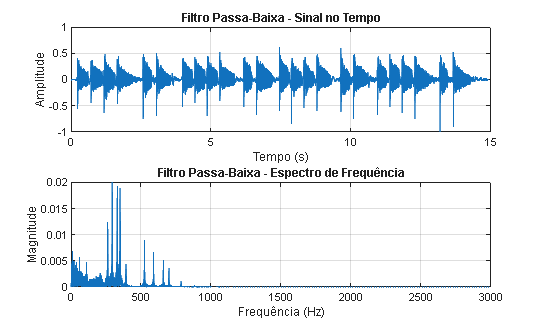

%%Equalização de 3 bandas
% Filtro Passa-Baixa
freq_min = 400; % Frequência de corte
ordem_min = 100; % Ordem do filtro
b_graves = fir1(ordem_min, freq_min/(FS/2), 'low');
Y_graves = filtfilt(b_graves, 1, Y);
Y_graves = Y_graves / max(abs(Y_graves)); % Normalização
%sound(Y_graves, FS);
%pause(t + 1);

%% Filtro Passa-Banda
freq_min = 400;    % Frequência de corte inferior
freq_max = 900; % Frequência de corte superior
ordem_filt = 100;     % Ordem do filtro
b_medios = fir1(ordem_filt, [freq_min, freq_max]/(FS/2), 'bandpass');
Y_medios = filtfilt(b_medios, 1, Y);
Y_medios = Y_medios / max(abs(Y_medios)); % Normalização
%sound(Y_medios, FS);
%pause(t + 1);

% Filtro Passa-Alta
freq_max = 900; % Frequência de corte
ordem_max = 100; % Ordem do filtro
b_agudos = fir1(ordem_max, freq_max/(FS/2), 'high');
Y_agudos = filtfilt(b_agudos, 1, Y);
Y_agudos = Y_agudos / max(abs(Y_agudos)); % Normalização
%sound(Y_agudos, FS);
%pause(t + 1);

%Ganhos
ganho_graves = 1.0;
ganho_medios = 1.0;
ganho_agudos = 1.0;

% Áudio Equalizado
Y_equalizado = Y_graves*ganho_graves + Y_medios*ganho_medios + Y_agudos*ganho_agudos;
Y_equalizado = Y_equalizado / max(abs(Y_equalizado)); % Normalização
%sound(Y_equalizado, FS);
%pause(t + 1);

% Plotar sinais filtrados
graficos(t, Y_graves, FS, 'Filtro Passa-Baixa');

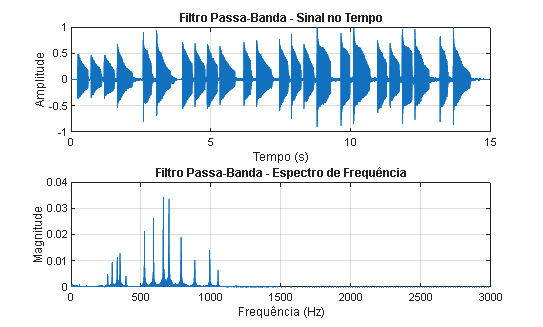

graficos(t, Y_medios, FS, 'Filtro Passa-Banda');

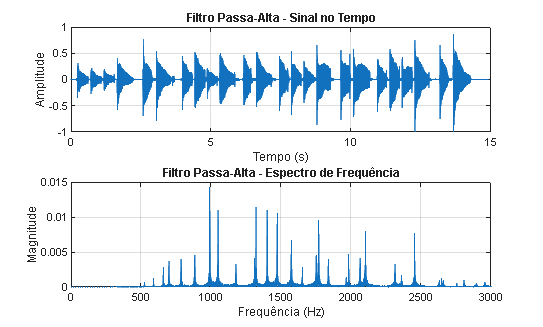

graficos(t, Y_agudos, FS, 'Filtro Passa-Alta');

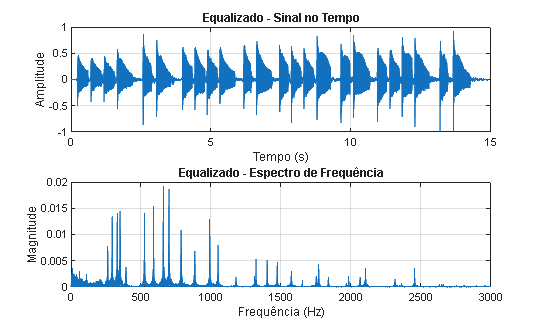

graficos(t, Y_equalizado, FS, 'Equalizado');


% Salvar áudios
if ~exist('Equalizacao', 'dir') %Criar pasta caso não existente
    mkdir('Equalizacao');
end

caminho_passa_baixa  = fullfile('Equalizacao', [nome_arquivo_audio '_passa_baixa.wav']); % Criar caminhos para a pasta
caminho_passa_banda  = fullfile('Equalizacao', [nome_arquivo_audio '_passa_banda.wav']);
caminho_passa_alta   = fullfile('Equalizacao', [nome_arquivo_audio '_passa_alta.wav']);
caminho_equalizado   = fullfile('Equalizacao', [nome_arquivo_audio '_equalizado.wav']);

audiowrite(caminho_passa_baixa, Y_graves, FS); % Salvar áudios na pasta
audiowrite(caminho_passa_banda, Y_medios, FS); 
audiowrite(caminho_passa_alta, Y_agudos, FS);
audiowrite(caminho_equalizado, Y_equalizado, FS);
disp('Áudios filtrados salvos.');

Áudios filtrados salvos.


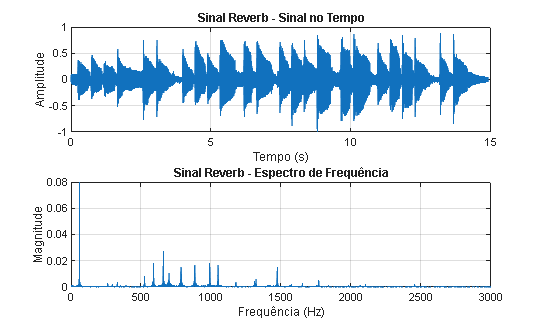

%%Resposta ao impulso + convolução
% Encontra o pico do impulso (onde a palma ocorreu)
[~, pico_idx] = max(abs(impulso));

% Define janela em torno do pico (ex.: 200 ms antes e 1 s depois)
janela_inicio = max(1, pico_idx - round(0.5 * Fs_impulso));
janela_fim    = min(length(impulso), pico_idx + round(0.5 * Fs_impulso));

impulso_cortado = impulso(janela_inicio:janela_fim);
impulso_cortado = impulso_cortado / max(abs(impulso_cortado)); % Normalização

% Convolução
Y_reverb = conv(Y, impulso_cortado, 'same');
Y_reverb = Y_reverb / max(abs(Y_reverb), [], 'all'); % Normalização
%sound(Y_reverb, Fs_impulso);
%pause(t + 1);

% Plotar sinal
graficos(t, Y_reverb, Fs_impulso, 'Sinal Reverb');


%Salvar áudio
if ~exist('Resposta_ao_impulso', 'dir')
    mkdir('Resposta_ao_impulso');
end

caminho_impulso  = fullfile('Resposta_ao_impulso', [nome_arquivo_impulso '_resposta_impulso.wav']);

audiowrite(caminho_impulso, Y_reverb, Fs_impulso);
disp('Resposta ao impulso + convolução salva.');

Resposta ao impulso + convolução salva.


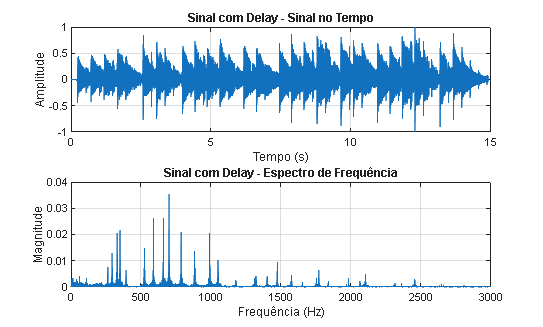

%%Efeitos Adicionais

% Efeito 1: Delay com Feedback(Delay loop)
D = round(0.3 * FS); % atraso de 300 ms
a = 0.5;             % atenuação do eco

% O sistema é: %y[n] = x[n]+a·y[n−D] 
b_delay = 1; % Numerador
a_delay = [1 zeros(1, D-1) -a]; % Denominador para feedback a em atraso D
Y_delay = filter(b_delay, a_delay, Y);
Y_delay = Y_delay / max(abs(Y_delay)); % Normaliza saída
%sound(Y_delay, FS);
%pause(t + 1);

% Efeito 2: Clipping suave(Waveshaping)
% O sistema é: y[n] = tanh(Gx[n])
G = 5; % ganho do clipping
Y_clip = tanh(G * Y);
Y_clip = Y_clip / max(abs(Y_clip));
%sound(Y_clip, FS);
%pause(t + 1);

% Efeito 3: Comb Filter (Comb)
% O sistema é: y[n] = x[n] + x[n − N].
N = round(0.01 * FS); % atraso de 10 ms
Y_shifted = [zeros(N,1); Y(1:end-N)];   % cria sinal atrasado do mesmo tamanho
Y_comb = Y + Y_shifted;
Y_comb = Y_comb / max(abs(Y_comb));
%sound(Y_comb, FS);
%pause(t + 1);

% Plotar Sinais
% Plotar sinais com efeitos adicionais
graficos(t, Y_delay, FS, 'Sinal com Delay');

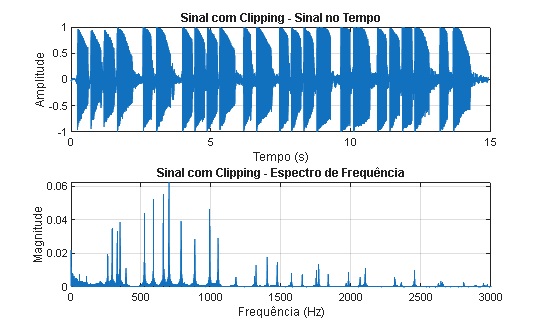

graficos(t, Y_clip, FS, 'Sinal com Clipping');

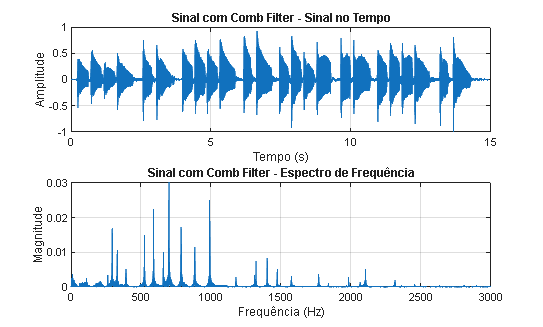

graficos(t, Y_comb, FS, 'Sinal com Comb Filter');


% Salvar áudio
if ~exist('Efeitos_Adicionais', 'dir')
    mkdir('Efeitos_Adicionais');
end

caminho_delay  = fullfile('Efeitos_Adicionais', [nome_arquivo_audio '_delay.wav']);
caminho_clipping  = fullfile('Efeitos_Adicionais', [nome_arquivo_audio '_clipping.wav']);
caminho_comb  = fullfile('Efeitos_Adicionais', [nome_arquivo_audio '_comb.wav']);

audiowrite(caminho_delay, Y_delay, FS);
audiowrite(caminho_clipping, Y_clip, FS);
audiowrite(caminho_comb, Y_comb, FS);
disp('Efeitos adicionais salvos.');

Efeitos adicionais salvos.


%% Funções Auxiliares
% Converte frequência (Hz) em nota musical e oitava.
function [nota, oitava] = freq_nota(freq)
    midiNumber = round(12 * log2(freq / 440) + 69); % Conversão da frequência para número MIDI
    notasTabela = {'C', 'C#', 'D', 'D#', 'E', 'F', 'F#', 'G', 'G#', 'A', 'A#', 'B'};
    oitava = floor((midiNumber - 12) / 12); % Calcula a oitava: MIDI 12 é C0, MIDI 24 é C1, etc.
    notaIndex = mod(midiNumber, 12) + 1; % Índice da nota dentro da oitava (1 a 12 para notas de C a B)
    nota = notasTabela{notaIndex}; % Seleciona a nota correspondente
end

% Plot dos gráficos necessários para análise
function graficos(t, Y, FS, titulo)
    figure;
    subplot(2,1,1);
    plot(t, Y);
    title([titulo ' - Sinal no Tempo']);
    xlabel('Tempo (s)'); 
    ylabel('Amplitude');
    grid on;
    
    N = length(Y);
    X = fft(Y);
    P2 = abs(X/N);
    P1 = P2(1:N/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    f = FS*(0:(N/2))/N;
    
    subplot(2,1,2);
    plot(f, P1);
    title([titulo ' - Espectro de Frequência']);
    xlabel('Frequência (Hz)'); 
    ylabel('Magnitude');
    grid on;
    xlim([0 3000]);

    if ~exist('Graficos', 'dir')
    mkdir('Graficos');
    end

    caminho_fig = fullfile('Graficos', [titulo '.png']);
    exportgraphics(gcf, caminho_fig, 'Resolution', 900);

end